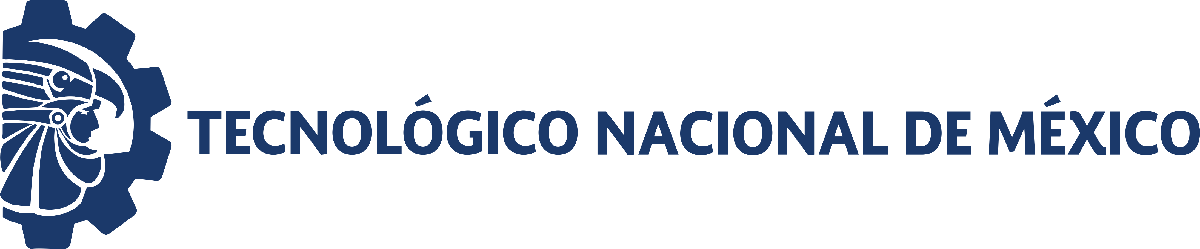                                 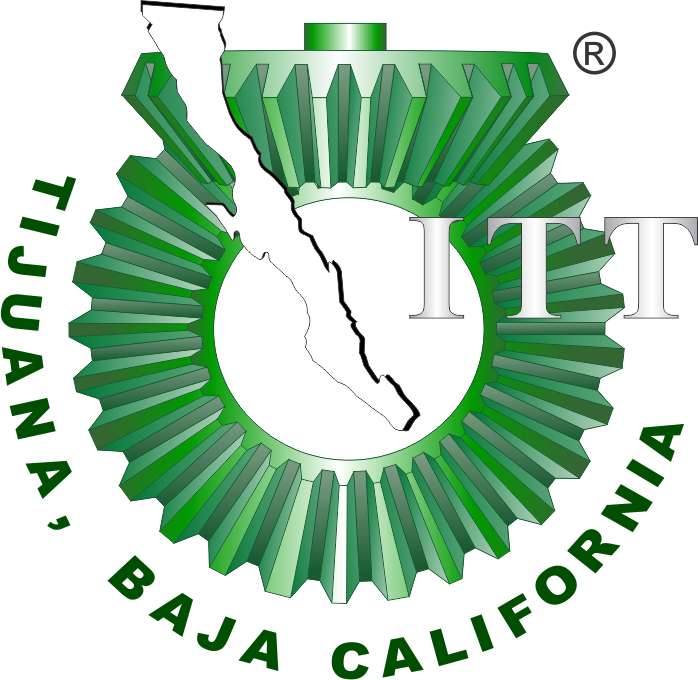

# Práctica: Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

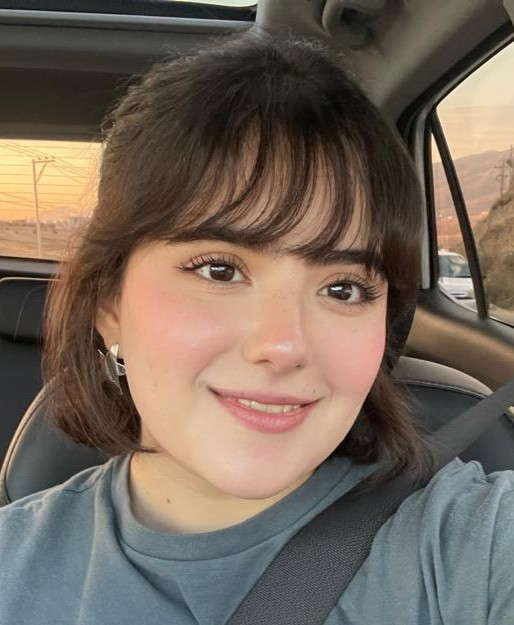

Nombre del alumno: **Nicole Zoe Camacho Quezada**

Número de control: **22211747**

Correo institucional: **L22211747@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')

tend = 180; % Tiempo de simulación en días
dt = 1E-3; % Intervalo para el método de solución por diferencias finitas
n = round(tend/dt); % Cantidad de iteraciones para el método numérico

% Condiciones iniciales base para cada paciente
x1_0= 59; x2_0 = 44; x3_0 = 885;
% Parametros particulares a cada paciente
gamma = [0.769, 0.388, 0.510, 0.590, 0.262, 0.324, 0.356, 0.089, 0.243, 0.057];
 beta = [1.650, 0.867, 1.617, 2.615, 1.518, 2.676, 0.891, 2.557, 0.925, 0.089];
% Intervalo para las condiciones inciales
xmin = 0.95; xmax = 1.05; 
seed = 22211747; % Semilla para asegurar reproducibilidad
rng(seed, 'twister')
interval = xmin + (xmax -xmin).*rand(1,numel(gamma));
% Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0);...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0);...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0);

x1(0) = 
   56.3662   56.3749   59.6322   60.2565   56.1576   58.5392   59.7709   58.2355   61.7724   59.1515



x2(0) = 
   42.0358   42.0423   44.4715   44.9370   41.8802   43.6564   44.5749   43.4299   46.0675   44.1129



x3(0) = 
  845.4935  845.6239  894.4837  903.8474  842.3636  878.0881  896.5640  873.5330  926.5854  887.2718



## Caso: Sin transfusión sanguínea

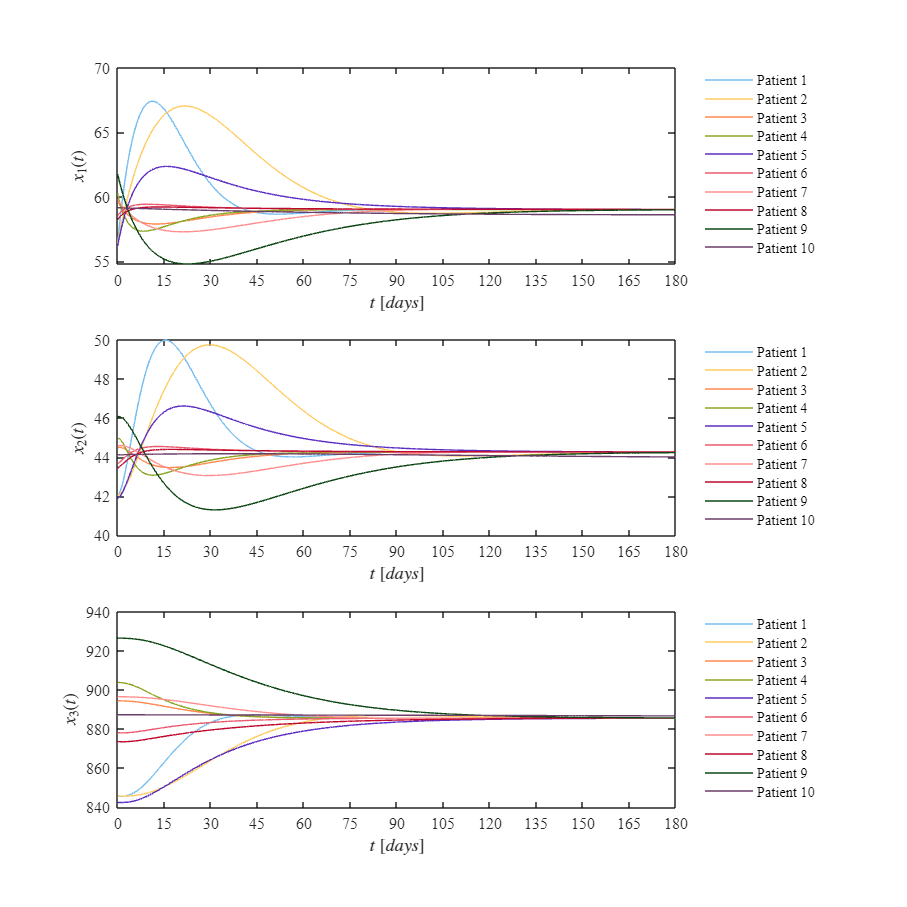

u=zeros(n+1,1);
fig=1;
for i=1:10
    [t,x1,x2,x3]= system(x1_0(i),x2_0(i),x3_0(i), beta(i), gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusión sanguínea

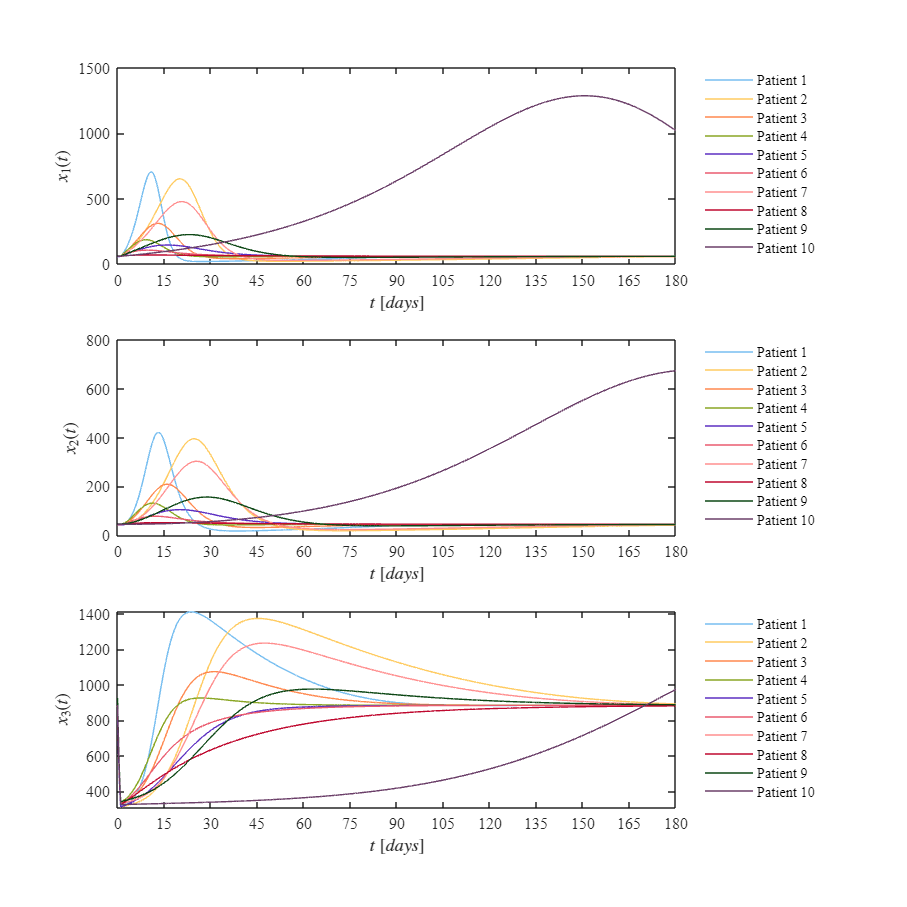

u= zeros(n+1,1); u(1:1/dt)=1;
fig=2;
for i=1:10
    [t,x1,x2,x3]= system(x1_0(i),x2_0(i),x3_0(i), beta(i), gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## **Funciones**

### **Modelo matematico**


$${\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\mathrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\mathrm{ase}} }$$



$${\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t, x1, x2, x3]=system(x1_0,x2_0,x3_0,beta, gamma,u,dt,tend)
    %Parametros fijos
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n= round(tend/dt);
    x1=zeros(n+1,1); x1(1)=x1_0;
    x2=zeros(n+1,1); x2(1)=x2_0;
    x3=zeros(n+1,1); x3(1)=x3_0;
    
    for i=1:n
        x1(i+1)=x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1)=x2(i) + (beta*(k1*x1(i) - k2*x2(i)))*dt;
        x3(i+1)=x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) -u(i)*x3(i))*dt;
    end
end

## Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig), 'Color', 'w')
    set(gcf,'units', 'Centimeters', 'Position', [1,1,20,20])
     mycolors = [119, 190, 240;
                255, 203, 097;
                255, 137, 079;
                138, 166, 036;
                092, 047, 194; 
                234, 091, 111;
                255, 143, 143
                191, 009, 047;
                013, 071, 021;
                107, 063, 105]/255;


 

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors); 
    plot(t,x1)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex', 'FontSize', 10)
    ylabel('$x_1(t)$', 'Interpreter', 'latex', 'FontSize', 10)
    xlim([0 180]); xticks(0:15:180)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    L= legend('Patient 1', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5',...
        'Patient 6', 'Patient 7', 'Patient 8', 'Patient 9', 'Patient 10');
    set(L,'FontSize', 9, 'Box', 'Off', 'Location', 'NorthEastOutside');


    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x2)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex', 'FontSize', 10)
    ylabel('$x_2(t)$', 'Interpreter', 'latex', 'FontSize', 10)
    xlim([0 180]); xticks(0:15:180)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    L= legend('Patient 1', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5',...
        'Patient 6', 'Patient 7', 'Patient 8', 'Patient 9', 'Patient 10');
    set(L,'FontSize', 9, 'Box', 'Off', 'Location', 'NorthEastOutside');

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x3)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex', 'FontSize', 10)
    ylabel('$x_3(t)$', 'Interpreter', 'latex', 'FontSize', 10)
    xlim([0 180]); xticks(0:15:180)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    L= legend('Patient 1', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5',...
        'Patient 6', 'Patient 7', 'Patient 8', 'Patient 9', 'Patient 10');
    set(L,'FontSize', 9, 'Box', 'Off', 'Location', 'NorthEastOutside');

    if fig == 1
        exportgraphics(gcf,'Caso Sin transfusion.pdf', 'ContentType','vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso Con transfusion.pdf', 'ContentType','vector')
    end
end
